mystartdefaults
num_method_final

discrete_bound1 =                    0   0.500000000000000   1.000000000000000   1.500000000000000   2.000000000000000   2.500000000000000   3.000000000000000   3.500000000000000   4.000000000000000   4.500000000000000   5.000000000000000   5.500000000000000   6.000000000000000   6.500000000000000   7.000000000000000   7.500000000000000   8.000000000000000   8.500000000000000   9.000000000000000   9.500000000000000  10.000000000000000  10.500000000000000  11.000000000000000  11.500000000000000  12.000000000000000  12.500000000000000  13.000000000000000  13.500000000000000  14.000000000000000  14.500000000000000  15.000000000000000


discrete_bound2 =   65.000000000000000  65.500000000000000  66.000000000000000  66.500000000000000  67.000000000000000  67.500000000000000  68.000000000000000  68.500000000000000  69.000000000000000  69.500000000000000  70.000000000000000  70.500000000000000  71.000000000000000  71.500000000000000  72.000000000000000  72.500000000000000  73.000000000000000  73.500000000000000  74.000000000000000  74.500000000000000  75.000000000000000  75.500000000000000  76.000000000000000  76.500000000000000  77.000000000000000  77.500000000000000  78.000000000000000  78.500000000000000  79.000000000000000  79.500000000000000  80.000000000000000


Lower energy bound (Ea) = 0.000000 eV
Upper energy bound (Eb) = 150.411749 eV


Question 2

% Energy range and step size
E_min = 0; % in eV
E_max = 0.3; % in eV
deltaE = 0.0005; % in eV

% Recombination time (lifetime)
tau = 1e-9; % 1 ns in seconds

% Array of energy values
% Energy E0
E0 = E_min:deltaE:E_max;
R_values = zeros(length(E0), 1);
T_values = zeros(length(E0), 1);
A_values = zeros(length(E0), 1);
% Space discretization inside potentials
% Inside U1
x1_min = 0;
x1_max = 80;

n = (x1_max - x1_min)/step_size;
n

n =    160


Create U

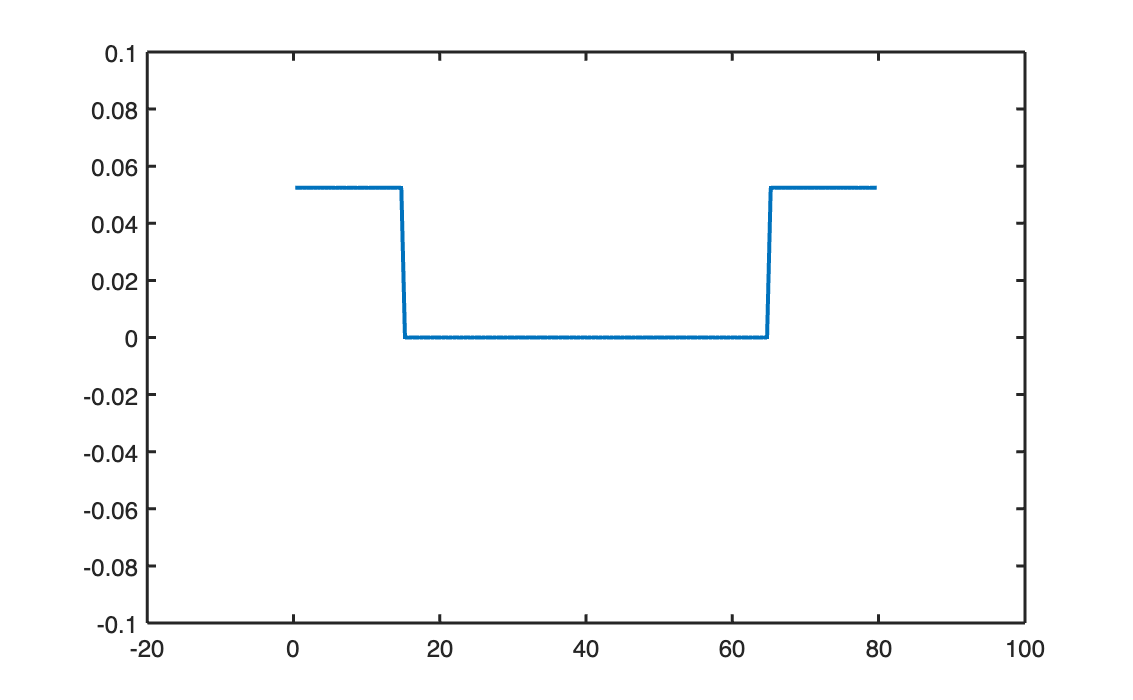

U = zeros(n, 1); % Potential barrier
x1 = zeros(n, 1);

for i = 1:n
    x1(i) = x1_min + step_size/2 + (i - 1) * step_size;
    if x1(i) <= 15
        U(i) = 0.2;
    elseif x1(i) >= 65 && x1(i) <= 80
        U(i) = 0.2;
    else
        U(i) = 0;
    end
    V(i) = U(i) / ekinscale;
end
plot(x1, V, 'LineWidth', 2);
xlim([-20 100]);
ylim([-0.1 0.1]);

Defining parameters

k_0 = zeros(1, length(E0));
for i = 1:length(E0)
    k_0(i) = sqrt(E0(i) / ekinscale);
end

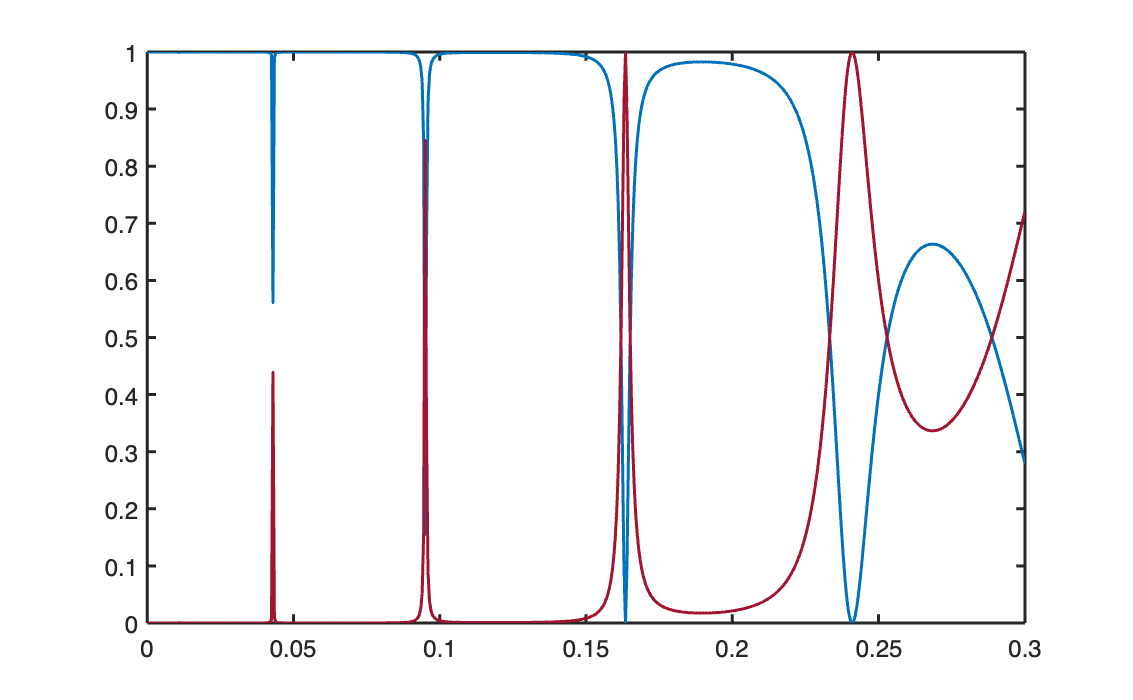

m = 2;
Phis = zeros(m, 1);
Phi = zeros(m, 1);
x = zeros(m, 1);
x(1) = x1_min - 1;
x(2) = x1_max + 1;
for k = 1:length(E0)
    if E0(k) == 0
        R_values(k) = 1;
        T_values(k) = 0;
        A_values(k) = 0;
    else
        Phi0p = exp(1i * k_0(k) * x1);
        G0 = zeros(n, n);
        for j = 1:n
            for i = 1:n
                G0(i, j) = step_size * exp(1i * k_0(k) * abs(x1(i) - x1(j))) / (2i * k_0(k));
            end
        end

        T = eye(n) - G0 * diag(V);
        Phip = T \ Phi0p;

        for i = 1:m
            Phis(i) = 0;
            for j = 1:n
                Phis(i) = Phis(i) + step_size * (exp(1i * k_0(k) * abs(x(i) - x1(j)))) / (2 * 1i * k_0(k)) * V(j) * Phip(j);
            end
        end
        Phi(i) = exp(1i * k_0(k) * x(i)) + Phis(i);
        R_values(k) = abs(Phis(1) / exp(1i * k_0(k) * x(1)))^2;
        T_values(k) = abs(Phi(2))^2;
        A_values(k) = 1 - R_values(k) - T_values(k);
    end
end
spec_graph = plot(E0, R_values, E0, T_values); % Plotting